question 2:

Hybrid images:

در ابتدا دو عکس را در ورودی میگیرد و پس از سیاه سفید کردن آنها ،یکی را با فیلتر پایین گذر و دیگری را با بالاگذر فیلتر میکنیم و حاصل را جمع میکنیم .

حال یکبار عکس را 8 برابر کرده تا مثل این شود که از نزدیک نگاه میکنیم در این حالت سگ را میبینیم بار دیگر تصویر را 0.2 کرده  و مثل اینست که از دور نگاه میکنیم در این حالت گربه را میبینیم

فیلتر پایین گذر به این صورت است که یک ماتریس مربعی با مرتبه فرد است که همه درایه های آن برابر یک تقسیم بر تعداد کل درایه هاست

فیلتر تمام گذر به این صورت است که یک ماتریس مربعی با مرتبه فرد که درایه وسطی ماتریس یک و بقیه صفرند

فیلتر بالاگدذر از کم کردن فیلتر میان گذز از تمام گذر بدست میاید

حال تصاویر را به وسیله 

imfilter 

در ماتریس های فیلتر کانوالو کرده و با هم جمع میکنبم و نشان میدهیم

نکته: هر سه فیلتر ماتریسشان از یک مرتبه است

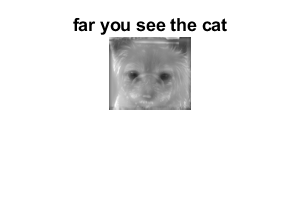

close all
clc
clear all

order=31;
w_ap=zeros(order);
w_ap((order+1)/2,(order+1)/2)=1;
w_lp=ones(order)/order^2;
w_hp=w_ap-w_lp;



cat_pic=(imread('hw2matlab\cat.jpg'));
gray_cat=rgb2gray(cat_pic);
gray_cat_filtered=imfilter(gray_cat,w_lp);


dog_pic=(imread('hw2matlab\dog.jpg'));
gray_dog=rgb2gray(dog_pic);
gray_dog_filtered=imfilter(gray_dog,w_hp);



final=imadd(gray_dog_filtered,gray_cat_filtered);




near = imresize(final, 8);
far=imresize(final, .2);

imshow(far)
title('far you see the cat')

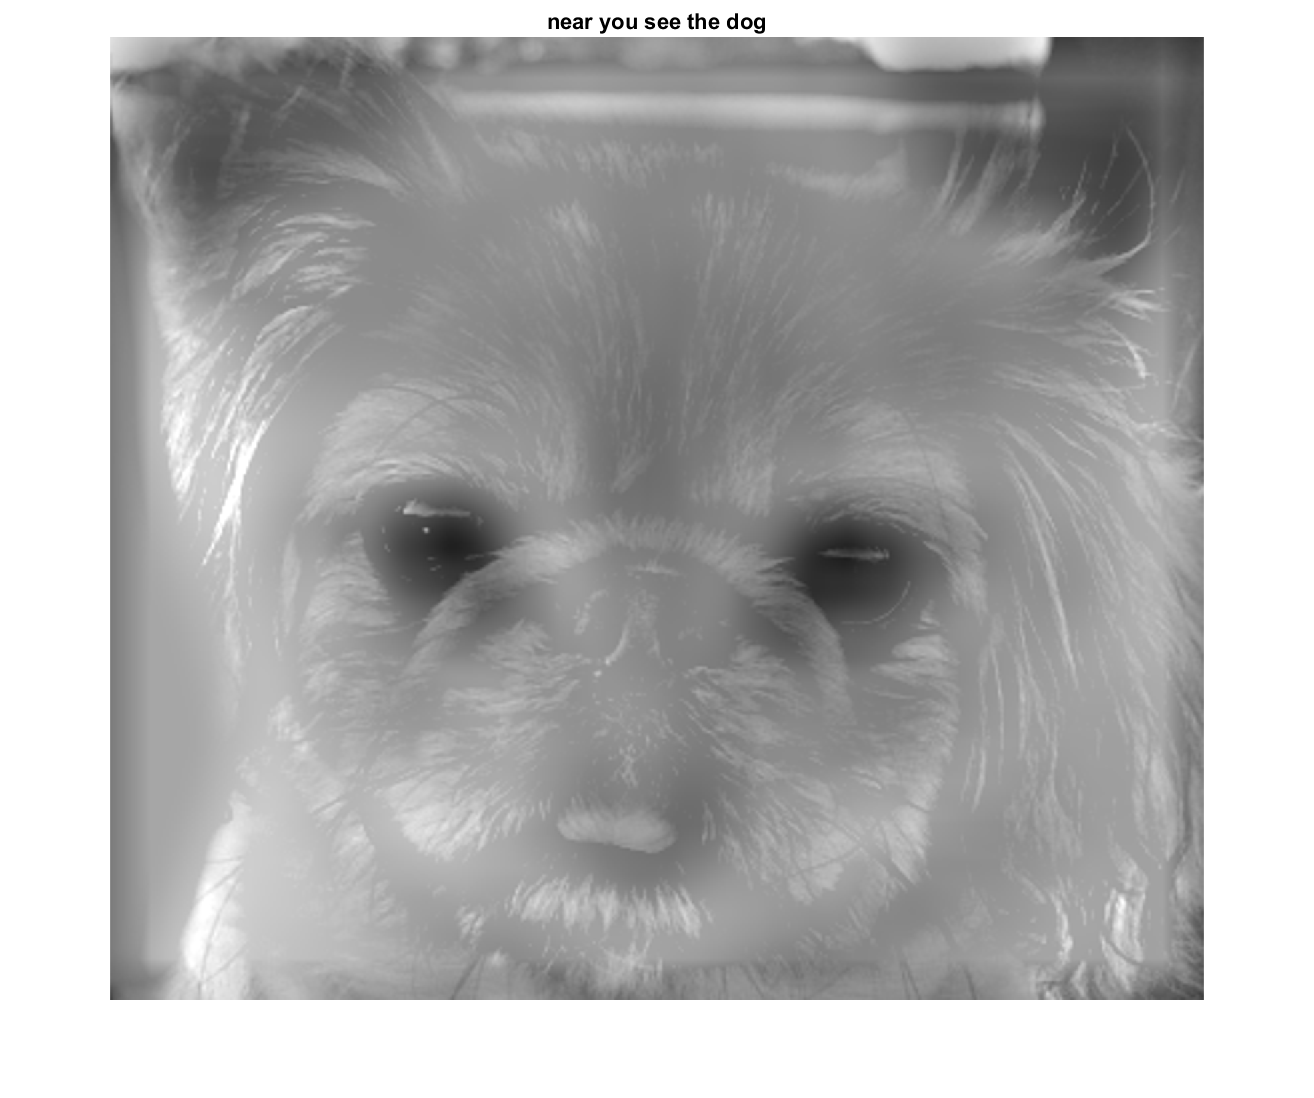


imshow(near)
title('near you see the dog')